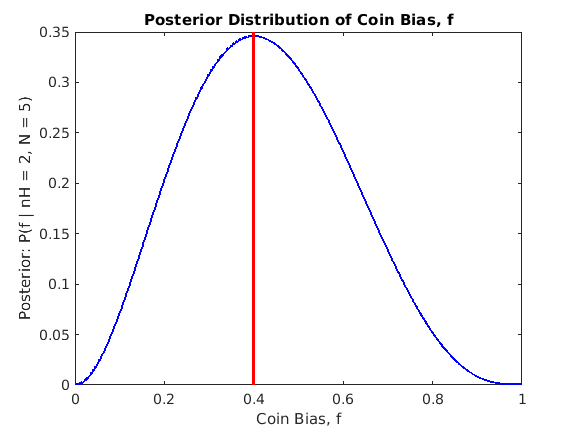

plotPosterior(2, 5)

% Goal: given values for nH, and N, plot the posterior function of the bent
% coin's bias. 
% nH = number of heads observed in N tosses
% N = total number of tosses
% f = bias (probability of heads) of the bent coin. 

function plotPosterior(nH, N)
    posterior = @(f) f.^ nH .* (1-f).^(N-nH) .* factorial(N)./(factorial(nH) .* factorial(N-nH));

    % maximum likelihood estimate of the bias, f
    maxLik = nH / N; 
    % value of posterior at the max likelihood value
    probMax = posterior(maxLik); 
    
    % Create values for f from 0 to 1, spaced out by 0.001
    f = 0 : 0.001 : 1; 

    % Plotting the posterior and a vertical line at f-hat, the maximum
    % likelihood estimate of the bias. 
    plot(f, posterior(f), 'b', 'LineWidth', 2)
    hold on; 
    yLimits = ylim;
    
    % add vertical line at max likelihood estimate of bias, f 
    plot([maxLik, maxLik], yLimits, 'r-', 'LineWidth', 2)
    
    title('Posterior Distribution of Coin Bias, f')
    xlabel('Coin Bias, f')
    ylabel(sprintf('Posterior: P(f | nH = %d, N = %d)', nH, N))
    
end

